clc
clear

% Import the data from .csv file
[t, toy, p, Ws1, Wd1, T1, Ws2, Wd2, T2, Ws3, Wd3, T3] = ...
    importfile('cex4WindDataInterpolated.csv');

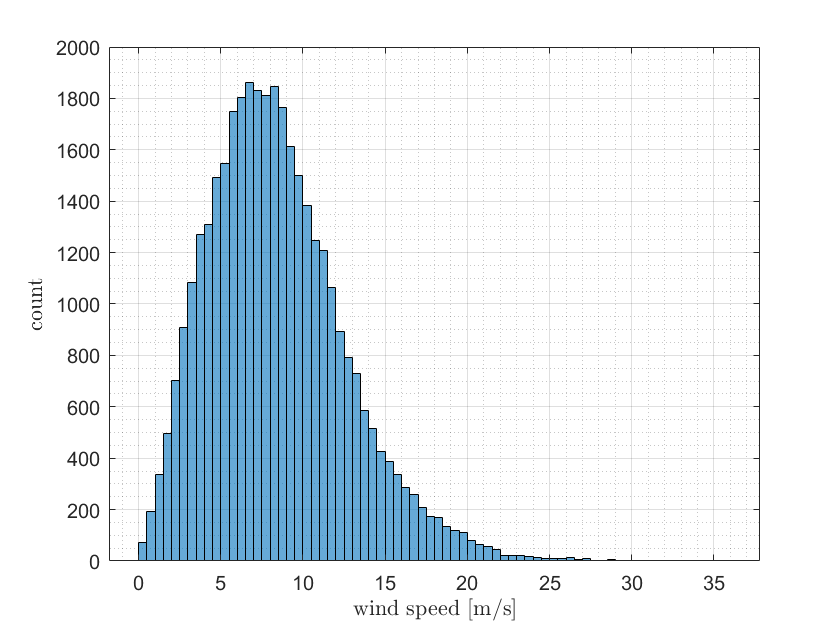

% Histogram of the wind speed
figure(1)
histogram(Ws1)
xlabel('wind speed [m/s]',"Interpreter","latex")
ylabel('count',"Interpreter","latex")
grid on; grid minor

% fit of a Weibull distribution
% From the 3rd moment and percentile F(mu)
mu = mean(Ws1,'omitnan')

mu = 8.3723

m3 = (sum(Ws1.^3,'omitnan'))/(numel(Ws1)-sum(isnan(Ws1)))

m3 = 1.0818e+03

Fmu = numel(Ws1(Ws1<mu))/(numel(Ws1)-sum(isnan(Ws1)))

Fmu = 0.5453

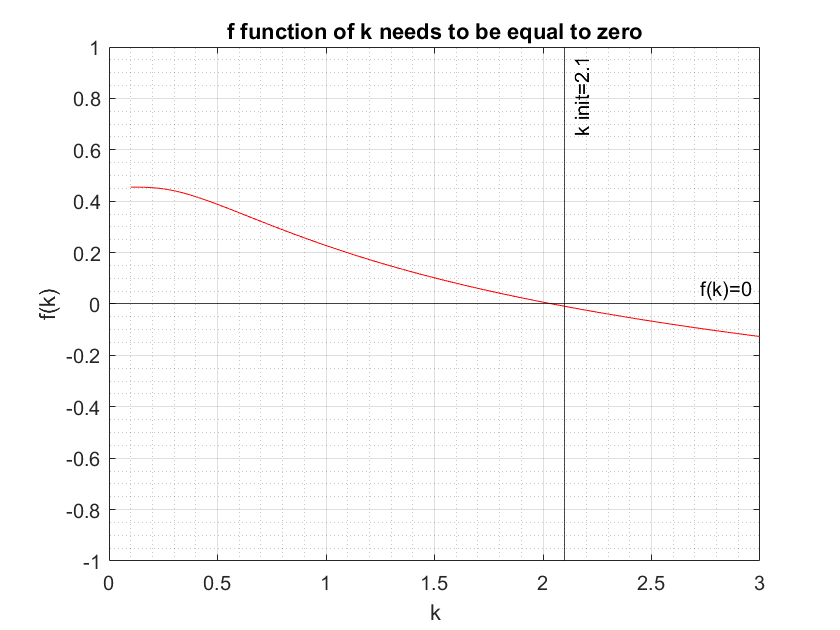


% Plot function f(k) which should be equal to 0
k_vect = 0.1:0.001:3;   
f_vect = 1-Fmu-exp(-((((mu^3)*gamma(1+(3./k_vect)))/m3).^(1/3)).^k_vect) ;

figure(12)
plot(k_vect,f_vect,'r-')
yline(0,'k','f(k)=0')
xline(2.1,'k','k init=2.1')
axis([0 3 -1 1])
xlabel('k')
ylabel('f(k)')
grid on; grid minor;
title('f function of k needs to be equal to zero')


% Find the zero of f(k)
k=2.1; % Initial guess
f = 1-Fmu-exp(-((((mu^3)*gamma(1+(3/k)))/m3)^(1/3))^k); 
while abs(f)>0.0001
    if f > 0
        k = k + 0.0001;
    end
    if f < 0
        k = k - 0.0001;
    end
    f = 1-Fmu-exp(-((((mu^3)*gamma(1+(3/k)))/m3)^(1/3))^k); 
end
k_Klim = k

k_Klim = 2.0448


%Calculation of A (Scale parameter)
A_Klim = (m3/gamma(1+(3/k)))^(1/3)

A_Klim = 9.4076

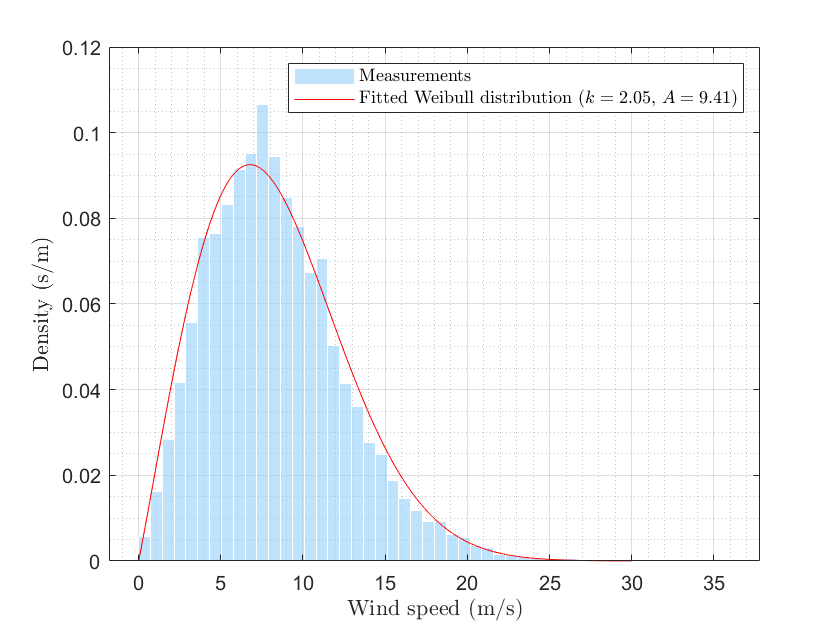

%Plot of Weibull distribution
U = 0:0.001:30;
P_Weibull = (k_Klim./U).*((U./A_Klim).^k_Klim).*exp(-(U./A_Klim).^k_Klim);

figure(13)
histogram(Ws1,50,'Normalization','pdf','FaceColor',[0.5843 0.8157 0.9882],'EdgeColor','w')
hold on
plot(U,P_Weibull,'r')
%title('Klim wind speed distribution')
xlabel('Wind speed (m/s)',"Interpreter","latex")
ylabel('Density (s/m)',"Interpreter","latex")
grid on; grid minor
legend({'Measurements','Fitted Weibull distribution ($k=2.05$, $A=9.41$)'},"Interpreter","latex")
hold off